# Create Deep Learning Network Architecture with Pretrained Parameters

Script for creating the layers for a deep learning network with the following properties:

Run the script to create the layers in the workspace variable `net`.

To learn more, see [Generate MATLAB Code From Deep Network Designer](matlab:helpview('deeplearning','generate_matlab_code')).

Auto-generated by MATLAB on 16-Dec-2024 11:23:30

By Nha Nguyen, 2024

Email:tnv.tainangviet@gmail.com

## Load Network Parameters

Load network parameters like weights, biases, or layers unsupported for network code generation from the stored parameters file.

if isfile("params_2024_12_16__11_22_39.mat")==0
    display('Please download params_2024_12_16__11_22_39.mat from the link below');
    display('https://www.dropbox.com/scl/fi/gir1kh438t1cwd7g5hl1z/params_2024_12_16__11_22_39.mat?rlkey=cpe6w1470vvhv7s67gy6fcgpk&dl=0');
else
params = load("params_2024_12_16__11_22_39.mat");

## Create dlnetwork

Create the dlnetwork variable to contain the network layers.

net = dlnetwork;

## Add Layer Branches

Add branches to the dlnetwork. Each branch is a linear array of layers.

tempNet = [
    image3dInputLayer([91 109 91 1],"Name","VideoInputLayer","Normalization","rescale-zero-one","Max",params.VideoInputLayer.Max,"Min",params.VideoInputLayer.Min)
    convolution3dLayer([7 7 7],64,"Name","conv1_Inflated","Padding","same","Stride",[2 2 2],"Bias",params.conv1_Inflated.Bias,"Weights",params.conv1_Inflated.Weights)
    batchNormalizationLayer("Name","bn_conv1_Inflated","Offset",params.bn_conv1_Inflated.Offset,"Scale",params.bn_conv1_Inflated.Scale,"TrainedMean",params.bn_conv1_Inflated.TrainedMean,"TrainedVariance",params.bn_conv1_Inflated.TrainedVariance)
    reluLayer("Name","conv1_relu")
    maxPooling3dLayer([3 3 3],"Name","pool1_Inflated","Padding","same","Stride",[2 2 2])];
net = addLayers(net,tempNet);

tempNet = [
    convolution3dLayer([1 1 1],64,"Name","res2a_branch2a_Inflated","Padding","same","Bias",params.res2a_branch2a_Inflated.Bias,"Weights",params.res2a_branch2a_Inflated.Weights)
    batchNormalizationLayer("Name","bn2a_branch2a_Inflated","Offset",params.bn2a_branch2a_Inflated.Offset,"Scale",params.bn2a_branch2a_Inflated.Scale,"TrainedMean",params.bn2a_branch2a_Inflated.TrainedMean,"TrainedVariance",params.bn2a_branch2a_Inflated.TrainedVariance)
    reluLayer("Name","res2a_branch2a_relu")
    convolution3dLayer([3 3 3],64,"Name","res2a_branch2b_Inflated","Padding","same","Bias",params.res2a_branch2b_Inflated.Bias,"Weights",params.res2a_branch2b_Inflated.Weights)
    batchNormalizationLayer("Name","bn2a_branch2b_Inflated","Offset",params.bn2a_branch2b_Inflated.Offset,"Scale",params.bn2a_branch2b_Inflated.Scale,"TrainedMean",params.bn2a_branch2b_Inflated.TrainedMean,"TrainedVariance",params.bn2a_branch2b_Inflated.TrainedVariance)
    reluLayer("Name","res2a_branch2b_relu")
    convolution3dLayer([1 1 1],256,"Name","res2a_branch2c_Inflated","Padding","same","Bias",params.res2a_branch2c_Inflated.Bias,"Weights",params.res2a_branch2c_Inflated.Weights)
    batchNormalizationLayer("Name","bn2a_branch2c_Inflated","Offset",params.bn2a_branch2c_Inflated.Offset,"Scale",params.bn2a_branch2c_Inflated.Scale,"TrainedMean",params.bn2a_branch2c_Inflated.TrainedMean,"TrainedVariance",params.bn2a_branch2c_Inflated.TrainedVariance)];
net = addLayers(net,tempNet);

tempNet = [
    convolution3dLayer([1 1 1],256,"Name","res2a_branch1_Inflated","Padding","same","Bias",params.res2a_branch1_Inflated.Bias,"Weights",params.res2a_branch1_Inflated.Weights)
    batchNormalizationLayer("Name","bn2a_branch1_Inflated","Offset",params.bn2a_branch1_Inflated.Offset,"Scale",params.bn2a_branch1_Inflated.Scale,"TrainedMean",params.bn2a_branch1_Inflated.TrainedMean,"TrainedVariance",params.bn2a_branch1_Inflated.TrainedVariance)];
net = addLayers(net,tempNet);

tempNet = [
    additionLayer(2,"Name","res2a")
    reluLayer("Name","res2a_relu")];
net = addLayers(net,tempNet);

tempNet = [
    convolution3dLayer([1 1 1],64,"Name","res2b_branch2a_Inflated","Padding","same","Bias",params.res2b_branch2a_Inflated.Bias,"Weights",params.res2b_branch2a_Inflated.Weights)
    batchNormalizationLayer("Name","bn2b_branch2a_Inflated","Offset",params.bn2b_branch2a_Inflated.Offset,"Scale",params.bn2b_branch2a_Inflated.Scale,"TrainedMean",params.bn2b_branch2a_Inflated.TrainedMean,"TrainedVariance",params.bn2b_branch2a_Inflated.TrainedVariance)
    reluLayer("Name","res2b_branch2a_relu")
    convolution3dLayer([3 3 3],64,"Name","res2b_branch2b_Inflated","Padding","same","Bias",params.res2b_branch2b_Inflated.Bias,"Weights",params.res2b_branch2b_Inflated.Weights)
    batchNormalizationLayer("Name","bn2b_branch2b_Inflated","Offset",params.bn2b_branch2b_Inflated.Offset,"Scale",params.bn2b_branch2b_Inflated.Scale,"TrainedMean",params.bn2b_branch2b_Inflated.TrainedMean,"TrainedVariance",params.bn2b_branch2b_Inflated.TrainedVariance)
    reluLayer("Name","res2b_branch2b_relu")
    convolution3dLayer([1 1 1],256,"Name","res2b_branch2c_Inflated","Padding","same","Bias",params.res2b_branch2c_Inflated.Bias,"Weights",params.res2b_branch2c_Inflated.Weights)
    batchNormalizationLayer("Name","bn2b_branch2c_Inflated","Offset",params.bn2b_branch2c_Inflated.Offset,"Scale",params.bn2b_branch2c_Inflated.Scale,"TrainedMean",params.bn2b_branch2c_Inflated.TrainedMean,"TrainedVariance",params.bn2b_branch2c_Inflated.TrainedVariance)];
net = addLayers(net,tempNet);

tempNet = [
    additionLayer(2,"Name","res2b")
    reluLayer("Name","res2b_relu")];
net = addLayers(net,tempNet);

tempNet = [
    convolution3dLayer([1 1 1],64,"Name","res2c_branch2a_Inflated","Padding","same","Bias",params.res2c_branch2a_Inflated.Bias,"Weights",params.res2c_branch2a_Inflated.Weights)
    batchNormalizationLayer("Name","bn2c_branch2a_Inflated","Offset",params.bn2c_branch2a_Inflated.Offset,"Scale",params.bn2c_branch2a_Inflated.Scale,"TrainedMean",params.bn2c_branch2a_Inflated.TrainedMean,"TrainedVariance",params.bn2c_branch2a_Inflated.TrainedVariance)
    reluLayer("Name","res2c_branch2a_relu")
    convolution3dLayer([3 3 3],64,"Name","res2c_branch2b_Inflated","Padding","same","Bias",params.res2c_branch2b_Inflated.Bias,"Weights",params.res2c_branch2b_Inflated.Weights)
    batchNormalizationLayer("Name","bn2c_branch2b_Inflated","Offset",params.bn2c_branch2b_Inflated.Offset,"Scale",params.bn2c_branch2b_Inflated.Scale,"TrainedMean",params.bn2c_branch2b_Inflated.TrainedMean,"TrainedVariance",params.bn2c_branch2b_Inflated.TrainedVariance)
    reluLayer("Name","res2c_branch2b_relu")
    convolution3dLayer([1 1 1],256,"Name","res2c_branch2c_Inflated","Padding","same","Bias",params.res2c_branch2c_Inflated.Bias,"Weights",params.res2c_branch2c_Inflated.Weights)
    batchNormalizationLayer("Name","bn2c_branch2c_Inflated","Offset",params.bn2c_branch2c_Inflated.Offset,"Scale",params.bn2c_branch2c_Inflated.Scale,"TrainedMean",params.bn2c_branch2c_Inflated.TrainedMean,"TrainedVariance",params.bn2c_branch2c_Inflated.TrainedVariance)];
net = addLayers(net,tempNet);

tempNet = [
    additionLayer(2,"Name","res2c")
    reluLayer("Name","res2c_relu")];
net = addLayers(net,tempNet);

tempNet = [
    convolution3dLayer([1 1 1],128,"Name","res3a_branch2a_Inflated","Padding","same","Stride",[2 2 2],"Bias",params.res3a_branch2a_Inflated.Bias,"Weights",params.res3a_branch2a_Inflated.Weights)
    batchNormalizationLayer("Name","bn3a_branch2a_Inflated","Offset",params.bn3a_branch2a_Inflated.Offset,"Scale",params.bn3a_branch2a_Inflated.Scale,"TrainedMean",params.bn3a_branch2a_Inflated.TrainedMean,"TrainedVariance",params.bn3a_branch2a_Inflated.TrainedVariance)
    reluLayer("Name","res3a_branch2a_relu")
    convolution3dLayer([3 3 3],128,"Name","res3a_branch2b_Inflated","Padding","same","Bias",params.res3a_branch2b_Inflated.Bias,"Weights",params.res3a_branch2b_Inflated.Weights)
    batchNormalizationLayer("Name","bn3a_branch2b_Inflated","Offset",params.bn3a_branch2b_Inflated.Offset,"Scale",params.bn3a_branch2b_Inflated.Scale,"TrainedMean",params.bn3a_branch2b_Inflated.TrainedMean,"TrainedVariance",params.bn3a_branch2b_Inflated.TrainedVariance)
    reluLayer("Name","res3a_branch2b_relu")
    convolution3dLayer([1 1 1],512,"Name","res3a_branch2c_Inflated","Padding","same","Bias",params.res3a_branch2c_Inflated.Bias,"Weights",params.res3a_branch2c_Inflated.Weights)
    batchNormalizationLayer("Name","bn3a_branch2c_Inflated","Offset",params.bn3a_branch2c_Inflated.Offset,"Scale",params.bn3a_branch2c_Inflated.Scale,"TrainedMean",params.bn3a_branch2c_Inflated.TrainedMean,"TrainedVariance",params.bn3a_branch2c_Inflated.TrainedVariance)];
net = addLayers(net,tempNet);

tempNet = [
    convolution3dLayer([1 1 1],512,"Name","res3a_branch1_Inflated","Padding","same","Stride",[2 2 2],"Bias",params.res3a_branch1_Inflated.Bias,"Weights",params.res3a_branch1_Inflated.Weights)
    batchNormalizationLayer("Name","bn3a_branch1_Inflated","Offset",params.bn3a_branch1_Inflated.Offset,"Scale",params.bn3a_branch1_Inflated.Scale,"TrainedMean",params.bn3a_branch1_Inflated.TrainedMean,"TrainedVariance",params.bn3a_branch1_Inflated.TrainedVariance)];
net = addLayers(net,tempNet);

tempNet = [
    additionLayer(2,"Name","res3a")
    reluLayer("Name","res3a_relu")];
net = addLayers(net,tempNet);

tempNet = [
    convolution3dLayer([1 1 1],128,"Name","res3b1_branch2a_Inflated","Padding","same","Bias",params.res3b1_branch2a_Inflated.Bias,"Weights",params.res3b1_branch2a_Inflated.Weights)
    batchNormalizationLayer("Name","bn3b1_branch2a_Inflated","Offset",params.bn3b1_branch2a_Inflated.Offset,"Scale",params.bn3b1_branch2a_Inflated.Scale,"TrainedMean",params.bn3b1_branch2a_Inflated.TrainedMean,"TrainedVariance",params.bn3b1_branch2a_Inflated.TrainedVariance)
    reluLayer("Name","res3b1_branch2a_relu")
    convolution3dLayer([3 3 3],128,"Name","res3b1_branch2b_Inflated","Padding","same","Bias",params.res3b1_branch2b_Inflated.Bias,"Weights",params.res3b1_branch2b_Inflated.Weights)
    batchNormalizationLayer("Name","bn3b1_branch2b_Inflated","Offset",params.bn3b1_branch2b_Inflated.Offset,"Scale",params.bn3b1_branch2b_Inflated.Scale,"TrainedMean",params.bn3b1_branch2b_Inflated.TrainedMean,"TrainedVariance",params.bn3b1_branch2b_Inflated.TrainedVariance)
    reluLayer("Name","res3b1_branch2b_relu")
    convolution3dLayer([1 1 1],512,"Name","res3b1_branch2c_Inflated","Padding","same","Bias",params.res3b1_branch2c_Inflated.Bias,"Weights",params.res3b1_branch2c_Inflated.Weights)
    batchNormalizationLayer("Name","bn3b1_branch2c_Inflated","Offset",params.bn3b1_branch2c_Inflated.Offset,"Scale",params.bn3b1_branch2c_Inflated.Scale,"TrainedMean",params.bn3b1_branch2c_Inflated.TrainedMean,"TrainedVariance",params.bn3b1_branch2c_Inflated.TrainedVariance)];
net = addLayers(net,tempNet);

tempNet = [
    additionLayer(2,"Name","res3b1")
    reluLayer("Name","res3b1_relu")];
net = addLayers(net,tempNet);

tempNet = [
    convolution3dLayer([1 1 1],128,"Name","res3b2_branch2a_Inflated","Padding","same","Bias",params.res3b2_branch2a_Inflated.Bias,"Weights",params.res3b2_branch2a_Inflated.Weights)
    batchNormalizationLayer("Name","bn3b2_branch2a_Inflated","Offset",params.bn3b2_branch2a_Inflated.Offset,"Scale",params.bn3b2_branch2a_Inflated.Scale,"TrainedMean",params.bn3b2_branch2a_Inflated.TrainedMean,"TrainedVariance",params.bn3b2_branch2a_Inflated.TrainedVariance)
    reluLayer("Name","res3b2_branch2a_relu")
    convolution3dLayer([3 3 3],128,"Name","res3b2_branch2b_Inflated","Padding","same","Bias",params.res3b2_branch2b_Inflated.Bias,"Weights",params.res3b2_branch2b_Inflated.Weights)
    batchNormalizationLayer("Name","bn3b2_branch2b_Inflated","Offset",params.bn3b2_branch2b_Inflated.Offset,"Scale",params.bn3b2_branch2b_Inflated.Scale,"TrainedMean",params.bn3b2_branch2b_Inflated.TrainedMean,"TrainedVariance",params.bn3b2_branch2b_Inflated.TrainedVariance)
    reluLayer("Name","res3b2_branch2b_relu")
    convolution3dLayer([1 1 1],512,"Name","res3b2_branch2c_Inflated","Padding","same","Bias",params.res3b2_branch2c_Inflated.Bias,"Weights",params.res3b2_branch2c_Inflated.Weights)
    batchNormalizationLayer("Name","bn3b2_branch2c_Inflated","Offset",params.bn3b2_branch2c_Inflated.Offset,"Scale",params.bn3b2_branch2c_Inflated.Scale,"TrainedMean",params.bn3b2_branch2c_Inflated.TrainedMean,"TrainedVariance",params.bn3b2_branch2c_Inflated.TrainedVariance)];
net = addLayers(net,tempNet);

tempNet = [
    additionLayer(2,"Name","res3b2")
    reluLayer("Name","res3b2_relu")];
net = addLayers(net,tempNet);

tempNet = [
    convolution3dLayer([1 1 1],128,"Name","res3b3_branch2a_Inflated","Padding","same","Bias",params.res3b3_branch2a_Inflated.Bias,"Weights",params.res3b3_branch2a_Inflated.Weights)
    batchNormalizationLayer("Name","bn3b3_branch2a_Inflated","Offset",params.bn3b3_branch2a_Inflated.Offset,"Scale",params.bn3b3_branch2a_Inflated.Scale,"TrainedMean",params.bn3b3_branch2a_Inflated.TrainedMean,"TrainedVariance",params.bn3b3_branch2a_Inflated.TrainedVariance)
    reluLayer("Name","res3b3_branch2a_relu")
    convolution3dLayer([3 3 3],128,"Name","res3b3_branch2b_Inflated","Padding","same","Bias",params.res3b3_branch2b_Inflated.Bias,"Weights",params.res3b3_branch2b_Inflated.Weights)
    batchNormalizationLayer("Name","bn3b3_branch2b_Inflated","Offset",params.bn3b3_branch2b_Inflated.Offset,"Scale",params.bn3b3_branch2b_Inflated.Scale,"TrainedMean",params.bn3b3_branch2b_Inflated.TrainedMean,"TrainedVariance",params.bn3b3_branch2b_Inflated.TrainedVariance)
    reluLayer("Name","res3b3_branch2b_relu")
    convolution3dLayer([1 1 1],512,"Name","res3b3_branch2c_Inflated","Padding","same","Bias",params.res3b3_branch2c_Inflated.Bias,"Weights",params.res3b3_branch2c_Inflated.Weights)
    batchNormalizationLayer("Name","bn3b3_branch2c_Inflated","Offset",params.bn3b3_branch2c_Inflated.Offset,"Scale",params.bn3b3_branch2c_Inflated.Scale,"TrainedMean",params.bn3b3_branch2c_Inflated.TrainedMean,"TrainedVariance",params.bn3b3_branch2c_Inflated.TrainedVariance)];
net = addLayers(net,tempNet);

tempNet = [
    additionLayer(2,"Name","res3b3")
    reluLayer("Name","res3b3_relu")];
net = addLayers(net,tempNet);

tempNet = [
    convolution3dLayer([1 1 1],256,"Name","res4a_branch2a_Inflated","Padding","same","Stride",[2 2 2],"Bias",params.res4a_branch2a_Inflated.Bias,"Weights",params.res4a_branch2a_Inflated.Weights)
    batchNormalizationLayer("Name","bn4a_branch2a_Inflated","Offset",params.bn4a_branch2a_Inflated.Offset,"Scale",params.bn4a_branch2a_Inflated.Scale,"TrainedMean",params.bn4a_branch2a_Inflated.TrainedMean,"TrainedVariance",params.bn4a_branch2a_Inflated.TrainedVariance)
    reluLayer("Name","res4a_branch2a_relu")
    convolution3dLayer([3 3 3],256,"Name","res4a_branch2b_Inflated","Padding","same","Bias",params.res4a_branch2b_Inflated.Bias,"Weights",params.res4a_branch2b_Inflated.Weights)
    batchNormalizationLayer("Name","bn4a_branch2b_Inflated","Offset",params.bn4a_branch2b_Inflated.Offset,"Scale",params.bn4a_branch2b_Inflated.Scale,"TrainedMean",params.bn4a_branch2b_Inflated.TrainedMean,"TrainedVariance",params.bn4a_branch2b_Inflated.TrainedVariance)
    reluLayer("Name","res4a_branch2b_relu")
    convolution3dLayer([1 1 1],1024,"Name","res4a_branch2c_Inflated","Padding","same","Bias",params.res4a_branch2c_Inflated.Bias,"Weights",params.res4a_branch2c_Inflated.Weights)
    batchNormalizationLayer("Name","bn4a_branch2c_Inflated","Offset",params.bn4a_branch2c_Inflated.Offset,"Scale",params.bn4a_branch2c_Inflated.Scale,"TrainedMean",params.bn4a_branch2c_Inflated.TrainedMean,"TrainedVariance",params.bn4a_branch2c_Inflated.TrainedVariance)];
net = addLayers(net,tempNet);

tempNet = [
    convolution3dLayer([1 1 1],1024,"Name","res4a_branch1_Inflated","Padding","same","Stride",[2 2 2],"Bias",params.res4a_branch1_Inflated.Bias,"Weights",params.res4a_branch1_Inflated.Weights)
    batchNormalizationLayer("Name","bn4a_branch1_Inflated","Offset",params.bn4a_branch1_Inflated.Offset,"Scale",params.bn4a_branch1_Inflated.Scale,"TrainedMean",params.bn4a_branch1_Inflated.TrainedMean,"TrainedVariance",params.bn4a_branch1_Inflated.TrainedVariance)];
net = addLayers(net,tempNet);

tempNet = [
    additionLayer(2,"Name","res4a")
    reluLayer("Name","res4a_relu")];
net = addLayers(net,tempNet);

tempNet = [
    convolution3dLayer([1 1 1],256,"Name","res4b1_branch2a_Inflated","Padding","same","Bias",params.res4b1_branch2a_Inflated.Bias,"Weights",params.res4b1_branch2a_Inflated.Weights)
    batchNormalizationLayer("Name","bn4b1_branch2a_Inflated","Offset",params.bn4b1_branch2a_Inflated.Offset,"Scale",params.bn4b1_branch2a_Inflated.Scale,"TrainedMean",params.bn4b1_branch2a_Inflated.TrainedMean,"TrainedVariance",params.bn4b1_branch2a_Inflated.TrainedVariance)
    reluLayer("Name","res4b1_branch2a_relu")
    convolution3dLayer([3 3 3],256,"Name","res4b1_branch2b_Inflated","Padding","same","Bias",params.res4b1_branch2b_Inflated.Bias,"Weights",params.res4b1_branch2b_Inflated.Weights)
    batchNormalizationLayer("Name","bn4b1_branch2b_Inflated","Offset",params.bn4b1_branch2b_Inflated.Offset,"Scale",params.bn4b1_branch2b_Inflated.Scale,"TrainedMean",params.bn4b1_branch2b_Inflated.TrainedMean,"TrainedVariance",params.bn4b1_branch2b_Inflated.TrainedVariance)
    reluLayer("Name","res4b1_branch2b_relu")
    convolution3dLayer([1 1 1],1024,"Name","res4b1_branch2c_Inflated","Padding","same","Bias",params.res4b1_branch2c_Inflated.Bias,"Weights",params.res4b1_branch2c_Inflated.Weights)
    batchNormalizationLayer("Name","bn4b1_branch2c_Inflated","Offset",params.bn4b1_branch2c_Inflated.Offset,"Scale",params.bn4b1_branch2c_Inflated.Scale,"TrainedMean",params.bn4b1_branch2c_Inflated.TrainedMean,"TrainedVariance",params.bn4b1_branch2c_Inflated.TrainedVariance)];
net = addLayers(net,tempNet);

tempNet = [
    additionLayer(2,"Name","res4b1")
    reluLayer("Name","res4b1_relu")];
net = addLayers(net,tempNet);

tempNet = [
    convolution3dLayer([1 1 1],256,"Name","res4b2_branch2a_Inflated","Padding","same","Bias",params.res4b2_branch2a_Inflated.Bias,"Weights",params.res4b2_branch2a_Inflated.Weights)
    batchNormalizationLayer("Name","bn4b2_branch2a_Inflated","Offset",params.bn4b2_branch2a_Inflated.Offset,"Scale",params.bn4b2_branch2a_Inflated.Scale,"TrainedMean",params.bn4b2_branch2a_Inflated.TrainedMean,"TrainedVariance",params.bn4b2_branch2a_Inflated.TrainedVariance)
    reluLayer("Name","res4b2_branch2a_relu")
    convolution3dLayer([3 3 3],256,"Name","res4b2_branch2b_Inflated","Padding","same","Bias",params.res4b2_branch2b_Inflated.Bias,"Weights",params.res4b2_branch2b_Inflated.Weights)
    batchNormalizationLayer("Name","bn4b2_branch2b_Inflated","Offset",params.bn4b2_branch2b_Inflated.Offset,"Scale",params.bn4b2_branch2b_Inflated.Scale,"TrainedMean",params.bn4b2_branch2b_Inflated.TrainedMean,"TrainedVariance",params.bn4b2_branch2b_Inflated.TrainedVariance)
    reluLayer("Name","res4b2_branch2b_relu")
    convolution3dLayer([1 1 1],1024,"Name","res4b2_branch2c_Inflated","Padding","same","Bias",params.res4b2_branch2c_Inflated.Bias,"Weights",params.res4b2_branch2c_Inflated.Weights)
    batchNormalizationLayer("Name","bn4b2_branch2c_Inflated","Offset",params.bn4b2_branch2c_Inflated.Offset,"Scale",params.bn4b2_branch2c_Inflated.Scale,"TrainedMean",params.bn4b2_branch2c_Inflated.TrainedMean,"TrainedVariance",params.bn4b2_branch2c_Inflated.TrainedVariance)];
net = addLayers(net,tempNet);

tempNet = [
    additionLayer(2,"Name","res4b2")
    reluLayer("Name","res4b2_relu")];
net = addLayers(net,tempNet);

tempNet = [
    convolution3dLayer([1 1 1],256,"Name","res4b3_branch2a_Inflated","Padding","same","Bias",params.res4b3_branch2a_Inflated.Bias,"Weights",params.res4b3_branch2a_Inflated.Weights)
    batchNormalizationLayer("Name","bn4b3_branch2a_Inflated","Offset",params.bn4b3_branch2a_Inflated.Offset,"Scale",params.bn4b3_branch2a_Inflated.Scale,"TrainedMean",params.bn4b3_branch2a_Inflated.TrainedMean,"TrainedVariance",params.bn4b3_branch2a_Inflated.TrainedVariance)
    reluLayer("Name","res4b3_branch2a_relu")
    convolution3dLayer([3 3 3],256,"Name","res4b3_branch2b_Inflated","Padding","same","Bias",params.res4b3_branch2b_Inflated.Bias,"Weights",params.res4b3_branch2b_Inflated.Weights)
    batchNormalizationLayer("Name","bn4b3_branch2b_Inflated","Offset",params.bn4b3_branch2b_Inflated.Offset,"Scale",params.bn4b3_branch2b_Inflated.Scale,"TrainedMean",params.bn4b3_branch2b_Inflated.TrainedMean,"TrainedVariance",params.bn4b3_branch2b_Inflated.TrainedVariance)
    reluLayer("Name","res4b3_branch2b_relu")
    convolution3dLayer([1 1 1],1024,"Name","res4b3_branch2c_Inflated","Padding","same","Bias",params.res4b3_branch2c_Inflated.Bias,"Weights",params.res4b3_branch2c_Inflated.Weights)
    batchNormalizationLayer("Name","bn4b3_branch2c_Inflated","Offset",params.bn4b3_branch2c_Inflated.Offset,"Scale",params.bn4b3_branch2c_Inflated.Scale,"TrainedMean",params.bn4b3_branch2c_Inflated.TrainedMean,"TrainedVariance",params.bn4b3_branch2c_Inflated.TrainedVariance)];
net = addLayers(net,tempNet);

tempNet = [
    additionLayer(2,"Name","res4b3")
    reluLayer("Name","res4b3_relu")];
net = addLayers(net,tempNet);

tempNet = [
    convolution3dLayer([1 1 1],256,"Name","res4b4_branch2a_Inflated","Padding","same","Bias",params.res4b4_branch2a_Inflated.Bias,"Weights",params.res4b4_branch2a_Inflated.Weights)
    batchNormalizationLayer("Name","bn4b4_branch2a_Inflated","Offset",params.bn4b4_branch2a_Inflated.Offset,"Scale",params.bn4b4_branch2a_Inflated.Scale,"TrainedMean",params.bn4b4_branch2a_Inflated.TrainedMean,"TrainedVariance",params.bn4b4_branch2a_Inflated.TrainedVariance)
    reluLayer("Name","res4b4_branch2a_relu")
    convolution3dLayer([3 3 3],256,"Name","res4b4_branch2b_Inflated","Padding","same","Bias",params.res4b4_branch2b_Inflated.Bias,"Weights",params.res4b4_branch2b_Inflated.Weights)
    batchNormalizationLayer("Name","bn4b4_branch2b_Inflated","Offset",params.bn4b4_branch2b_Inflated.Offset,"Scale",params.bn4b4_branch2b_Inflated.Scale,"TrainedMean",params.bn4b4_branch2b_Inflated.TrainedMean,"TrainedVariance",params.bn4b4_branch2b_Inflated.TrainedVariance)
    reluLayer("Name","res4b4_branch2b_relu")
    convolution3dLayer([1 1 1],1024,"Name","res4b4_branch2c_Inflated","Padding","same","Bias",params.res4b4_branch2c_Inflated.Bias,"Weights",params.res4b4_branch2c_Inflated.Weights)
    batchNormalizationLayer("Name","bn4b4_branch2c_Inflated","Offset",params.bn4b4_branch2c_Inflated.Offset,"Scale",params.bn4b4_branch2c_Inflated.Scale,"TrainedMean",params.bn4b4_branch2c_Inflated.TrainedMean,"TrainedVariance",params.bn4b4_branch2c_Inflated.TrainedVariance)];
net = addLayers(net,tempNet);

tempNet = [
    additionLayer(2,"Name","res4b4")
    reluLayer("Name","res4b4_relu")];
net = addLayers(net,tempNet);

tempNet = [
    convolution3dLayer([1 1 1],256,"Name","res4b5_branch2a_Inflated","Padding","same","Bias",params.res4b5_branch2a_Inflated.Bias,"Weights",params.res4b5_branch2a_Inflated.Weights)
    batchNormalizationLayer("Name","bn4b5_branch2a_Inflated","Offset",params.bn4b5_branch2a_Inflated.Offset,"Scale",params.bn4b5_branch2a_Inflated.Scale,"TrainedMean",params.bn4b5_branch2a_Inflated.TrainedMean,"TrainedVariance",params.bn4b5_branch2a_Inflated.TrainedVariance)
    reluLayer("Name","res4b5_branch2a_relu")
    convolution3dLayer([3 3 3],256,"Name","res4b5_branch2b_Inflated","Padding","same","Bias",params.res4b5_branch2b_Inflated.Bias,"Weights",params.res4b5_branch2b_Inflated.Weights)
    batchNormalizationLayer("Name","bn4b5_branch2b_Inflated","Offset",params.bn4b5_branch2b_Inflated.Offset,"Scale",params.bn4b5_branch2b_Inflated.Scale,"TrainedMean",params.bn4b5_branch2b_Inflated.TrainedMean,"TrainedVariance",params.bn4b5_branch2b_Inflated.TrainedVariance)
    reluLayer("Name","res4b5_branch2b_relu")
    convolution3dLayer([1 1 1],1024,"Name","res4b5_branch2c_Inflated","Padding","same","Bias",params.res4b5_branch2c_Inflated.Bias,"Weights",params.res4b5_branch2c_Inflated.Weights)
    batchNormalizationLayer("Name","bn4b5_branch2c_Inflated","Offset",params.bn4b5_branch2c_Inflated.Offset,"Scale",params.bn4b5_branch2c_Inflated.Scale,"TrainedMean",params.bn4b5_branch2c_Inflated.TrainedMean,"TrainedVariance",params.bn4b5_branch2c_Inflated.TrainedVariance)];
net = addLayers(net,tempNet);

tempNet = [
    additionLayer(2,"Name","res4b5")
    reluLayer("Name","res4b5_relu")];
net = addLayers(net,tempNet);

tempNet = [
    convolution3dLayer([1 1 1],256,"Name","res4b6_branch2a_Inflated","Padding","same","Bias",params.res4b6_branch2a_Inflated.Bias,"Weights",params.res4b6_branch2a_Inflated.Weights)
    batchNormalizationLayer("Name","bn4b6_branch2a_Inflated","Offset",params.bn4b6_branch2a_Inflated.Offset,"Scale",params.bn4b6_branch2a_Inflated.Scale,"TrainedMean",params.bn4b6_branch2a_Inflated.TrainedMean,"TrainedVariance",params.bn4b6_branch2a_Inflated.TrainedVariance)
    reluLayer("Name","res4b6_branch2a_relu")
    convolution3dLayer([3 3 3],256,"Name","res4b6_branch2b_Inflated","Padding","same","Bias",params.res4b6_branch2b_Inflated.Bias,"Weights",params.res4b6_branch2b_Inflated.Weights)
    batchNormalizationLayer("Name","bn4b6_branch2b_Inflated","Offset",params.bn4b6_branch2b_Inflated.Offset,"Scale",params.bn4b6_branch2b_Inflated.Scale,"TrainedMean",params.bn4b6_branch2b_Inflated.TrainedMean,"TrainedVariance",params.bn4b6_branch2b_Inflated.TrainedVariance)
    reluLayer("Name","res4b6_branch2b_relu")
    convolution3dLayer([1 1 1],1024,"Name","res4b6_branch2c_Inflated","Padding","same","Bias",params.res4b6_branch2c_Inflated.Bias,"Weights",params.res4b6_branch2c_Inflated.Weights)
    batchNormalizationLayer("Name","bn4b6_branch2c_Inflated","Offset",params.bn4b6_branch2c_Inflated.Offset,"Scale",params.bn4b6_branch2c_Inflated.Scale,"TrainedMean",params.bn4b6_branch2c_Inflated.TrainedMean,"TrainedVariance",params.bn4b6_branch2c_Inflated.TrainedVariance)];
net = addLayers(net,tempNet);

tempNet = [
    additionLayer(2,"Name","res4b6")
    reluLayer("Name","res4b6_relu")];
net = addLayers(net,tempNet);

tempNet = [
    convolution3dLayer([1 1 1],256,"Name","res4b7_branch2a_Inflated","Padding","same","Bias",params.res4b7_branch2a_Inflated.Bias,"Weights",params.res4b7_branch2a_Inflated.Weights)
    batchNormalizationLayer("Name","bn4b7_branch2a_Inflated","Offset",params.bn4b7_branch2a_Inflated.Offset,"Scale",params.bn4b7_branch2a_Inflated.Scale,"TrainedMean",params.bn4b7_branch2a_Inflated.TrainedMean,"TrainedVariance",params.bn4b7_branch2a_Inflated.TrainedVariance)
    reluLayer("Name","res4b7_branch2a_relu")
    convolution3dLayer([3 3 3],256,"Name","res4b7_branch2b_Inflated","Padding","same","Bias",params.res4b7_branch2b_Inflated.Bias,"Weights",params.res4b7_branch2b_Inflated.Weights)
    batchNormalizationLayer("Name","bn4b7_branch2b_Inflated","Offset",params.bn4b7_branch2b_Inflated.Offset,"Scale",params.bn4b7_branch2b_Inflated.Scale,"TrainedMean",params.bn4b7_branch2b_Inflated.TrainedMean,"TrainedVariance",params.bn4b7_branch2b_Inflated.TrainedVariance)
    reluLayer("Name","res4b7_branch2b_relu")
    convolution3dLayer([1 1 1],1024,"Name","res4b7_branch2c_Inflated","Padding","same","Bias",params.res4b7_branch2c_Inflated.Bias,"Weights",params.res4b7_branch2c_Inflated.Weights)
    batchNormalizationLayer("Name","bn4b7_branch2c_Inflated","Offset",params.bn4b7_branch2c_Inflated.Offset,"Scale",params.bn4b7_branch2c_Inflated.Scale,"TrainedMean",params.bn4b7_branch2c_Inflated.TrainedMean,"TrainedVariance",params.bn4b7_branch2c_Inflated.TrainedVariance)];
net = addLayers(net,tempNet);

tempNet = [
    additionLayer(2,"Name","res4b7")
    reluLayer("Name","res4b7_relu")];
net = addLayers(net,tempNet);

tempNet = [
    convolution3dLayer([1 1 1],256,"Name","res4b8_branch2a_Inflated","Padding","same","Bias",params.res4b8_branch2a_Inflated.Bias,"Weights",params.res4b8_branch2a_Inflated.Weights)
    batchNormalizationLayer("Name","bn4b8_branch2a_Inflated","Offset",params.bn4b8_branch2a_Inflated.Offset,"Scale",params.bn4b8_branch2a_Inflated.Scale,"TrainedMean",params.bn4b8_branch2a_Inflated.TrainedMean,"TrainedVariance",params.bn4b8_branch2a_Inflated.TrainedVariance)
    reluLayer("Name","res4b8_branch2a_relu")
    convolution3dLayer([3 3 3],256,"Name","res4b8_branch2b_Inflated","Padding","same","Bias",params.res4b8_branch2b_Inflated.Bias,"Weights",params.res4b8_branch2b_Inflated.Weights)
    batchNormalizationLayer("Name","bn4b8_branch2b_Inflated","Offset",params.bn4b8_branch2b_Inflated.Offset,"Scale",params.bn4b8_branch2b_Inflated.Scale,"TrainedMean",params.bn4b8_branch2b_Inflated.TrainedMean,"TrainedVariance",params.bn4b8_branch2b_Inflated.TrainedVariance)
    reluLayer("Name","res4b8_branch2b_relu")
    convolution3dLayer([1 1 1],1024,"Name","res4b8_branch2c_Inflated","Padding","same","Bias",params.res4b8_branch2c_Inflated.Bias,"Weights",params.res4b8_branch2c_Inflated.Weights)
    batchNormalizationLayer("Name","bn4b8_branch2c_Inflated","Offset",params.bn4b8_branch2c_Inflated.Offset,"Scale",params.bn4b8_branch2c_Inflated.Scale,"TrainedMean",params.bn4b8_branch2c_Inflated.TrainedMean,"TrainedVariance",params.bn4b8_branch2c_Inflated.TrainedVariance)];
net = addLayers(net,tempNet);

tempNet = [
    additionLayer(2,"Name","res4b8")
    reluLayer("Name","res4b8_relu")];
net = addLayers(net,tempNet);

tempNet = [
    convolution3dLayer([1 1 1],256,"Name","res4b9_branch2a_Inflated","Padding","same","Bias",params.res4b9_branch2a_Inflated.Bias,"Weights",params.res4b9_branch2a_Inflated.Weights)
    batchNormalizationLayer("Name","bn4b9_branch2a_Inflated","Offset",params.bn4b9_branch2a_Inflated.Offset,"Scale",params.bn4b9_branch2a_Inflated.Scale,"TrainedMean",params.bn4b9_branch2a_Inflated.TrainedMean,"TrainedVariance",params.bn4b9_branch2a_Inflated.TrainedVariance)
    reluLayer("Name","res4b9_branch2a_relu")
    convolution3dLayer([3 3 3],256,"Name","res4b9_branch2b_Inflated","Padding","same","Bias",params.res4b9_branch2b_Inflated.Bias,"Weights",params.res4b9_branch2b_Inflated.Weights)
    batchNormalizationLayer("Name","bn4b9_branch2b_Inflated","Offset",params.bn4b9_branch2b_Inflated.Offset,"Scale",params.bn4b9_branch2b_Inflated.Scale,"TrainedMean",params.bn4b9_branch2b_Inflated.TrainedMean,"TrainedVariance",params.bn4b9_branch2b_Inflated.TrainedVariance)
    reluLayer("Name","res4b9_branch2b_relu")
    convolution3dLayer([1 1 1],1024,"Name","res4b9_branch2c_Inflated","Padding","same","Bias",params.res4b9_branch2c_Inflated.Bias,"Weights",params.res4b9_branch2c_Inflated.Weights)
    batchNormalizationLayer("Name","bn4b9_branch2c_Inflated","Offset",params.bn4b9_branch2c_Inflated.Offset,"Scale",params.bn4b9_branch2c_Inflated.Scale,"TrainedMean",params.bn4b9_branch2c_Inflated.TrainedMean,"TrainedVariance",params.bn4b9_branch2c_Inflated.TrainedVariance)];
net = addLayers(net,tempNet);

tempNet = [
    additionLayer(2,"Name","res4b9")
    reluLayer("Name","res4b9_relu")];
net = addLayers(net,tempNet);

tempNet = [
    convolution3dLayer([1 1 1],256,"Name","res4b10_branch2a_Inflated","Padding","same","Bias",params.res4b10_branch2a_Inflated.Bias,"Weights",params.res4b10_branch2a_Inflated.Weights)
    batchNormalizationLayer("Name","bn4b10_branch2a_Inflated","Offset",params.bn4b10_branch2a_Inflated.Offset,"Scale",params.bn4b10_branch2a_Inflated.Scale,"TrainedMean",params.bn4b10_branch2a_Inflated.TrainedMean,"TrainedVariance",params.bn4b10_branch2a_Inflated.TrainedVariance)
    reluLayer("Name","res4b10_branch2a_relu")
    convolution3dLayer([3 3 3],256,"Name","res4b10_branch2b_Inflated","Padding","same","Bias",params.res4b10_branch2b_Inflated.Bias,"Weights",params.res4b10_branch2b_Inflated.Weights)
    batchNormalizationLayer("Name","bn4b10_branch2b_Inflated","Offset",params.bn4b10_branch2b_Inflated.Offset,"Scale",params.bn4b10_branch2b_Inflated.Scale,"TrainedMean",params.bn4b10_branch2b_Inflated.TrainedMean,"TrainedVariance",params.bn4b10_branch2b_Inflated.TrainedVariance)
    reluLayer("Name","res4b10_branch2b_relu")
    convolution3dLayer([1 1 1],1024,"Name","res4b10_branch2c_Inflated","Padding","same","Bias",params.res4b10_branch2c_Inflated.Bias,"Weights",params.res4b10_branch2c_Inflated.Weights)
    batchNormalizationLayer("Name","bn4b10_branch2c_Inflated","Offset",params.bn4b10_branch2c_Inflated.Offset,"Scale",params.bn4b10_branch2c_Inflated.Scale,"TrainedMean",params.bn4b10_branch2c_Inflated.TrainedMean,"TrainedVariance",params.bn4b10_branch2c_Inflated.TrainedVariance)];
net = addLayers(net,tempNet);

tempNet = [
    additionLayer(2,"Name","res4b10")
    reluLayer("Name","res4b10_relu")];
net = addLayers(net,tempNet);

tempNet = [
    convolution3dLayer([1 1 1],256,"Name","res4b11_branch2a_Inflated","Padding","same","Bias",params.res4b11_branch2a_Inflated.Bias,"Weights",params.res4b11_branch2a_Inflated.Weights)
    batchNormalizationLayer("Name","bn4b11_branch2a_Inflated","Offset",params.bn4b11_branch2a_Inflated.Offset,"Scale",params.bn4b11_branch2a_Inflated.Scale,"TrainedMean",params.bn4b11_branch2a_Inflated.TrainedMean,"TrainedVariance",params.bn4b11_branch2a_Inflated.TrainedVariance)
    reluLayer("Name","res4b11_branch2a_relu")
    convolution3dLayer([3 3 3],256,"Name","res4b11_branch2b_Inflated","Padding","same","Bias",params.res4b11_branch2b_Inflated.Bias,"Weights",params.res4b11_branch2b_Inflated.Weights)
    batchNormalizationLayer("Name","bn4b11_branch2b_Inflated","Offset",params.bn4b11_branch2b_Inflated.Offset,"Scale",params.bn4b11_branch2b_Inflated.Scale,"TrainedMean",params.bn4b11_branch2b_Inflated.TrainedMean,"TrainedVariance",params.bn4b11_branch2b_Inflated.TrainedVariance)
    reluLayer("Name","res4b11_branch2b_relu")
    convolution3dLayer([1 1 1],1024,"Name","res4b11_branch2c_Inflated","Padding","same","Bias",params.res4b11_branch2c_Inflated.Bias,"Weights",params.res4b11_branch2c_Inflated.Weights)
    batchNormalizationLayer("Name","bn4b11_branch2c_Inflated","Offset",params.bn4b11_branch2c_Inflated.Offset,"Scale",params.bn4b11_branch2c_Inflated.Scale,"TrainedMean",params.bn4b11_branch2c_Inflated.TrainedMean,"TrainedVariance",params.bn4b11_branch2c_Inflated.TrainedVariance)];
net = addLayers(net,tempNet);

tempNet = [
    additionLayer(2,"Name","res4b11")
    reluLayer("Name","res4b11_relu")];
net = addLayers(net,tempNet);

tempNet = [
    convolution3dLayer([1 1 1],256,"Name","res4b12_branch2a_Inflated","Padding","same","Bias",params.res4b12_branch2a_Inflated.Bias,"Weights",params.res4b12_branch2a_Inflated.Weights)
    batchNormalizationLayer("Name","bn4b12_branch2a_Inflated","Offset",params.bn4b12_branch2a_Inflated.Offset,"Scale",params.bn4b12_branch2a_Inflated.Scale,"TrainedMean",params.bn4b12_branch2a_Inflated.TrainedMean,"TrainedVariance",params.bn4b12_branch2a_Inflated.TrainedVariance)
    reluLayer("Name","res4b12_branch2a_relu")
    convolution3dLayer([3 3 3],256,"Name","res4b12_branch2b_Inflated","Padding","same","Bias",params.res4b12_branch2b_Inflated.Bias,"Weights",params.res4b12_branch2b_Inflated.Weights)
    batchNormalizationLayer("Name","bn4b12_branch2b_Inflated","Offset",params.bn4b12_branch2b_Inflated.Offset,"Scale",params.bn4b12_branch2b_Inflated.Scale,"TrainedMean",params.bn4b12_branch2b_Inflated.TrainedMean,"TrainedVariance",params.bn4b12_branch2b_Inflated.TrainedVariance)
    reluLayer("Name","res4b12_branch2b_relu")
    convolution3dLayer([1 1 1],1024,"Name","res4b12_branch2c_Inflated","Padding","same","Bias",params.res4b12_branch2c_Inflated.Bias,"Weights",params.res4b12_branch2c_Inflated.Weights)
    batchNormalizationLayer("Name","bn4b12_branch2c_Inflated","Offset",params.bn4b12_branch2c_Inflated.Offset,"Scale",params.bn4b12_branch2c_Inflated.Scale,"TrainedMean",params.bn4b12_branch2c_Inflated.TrainedMean,"TrainedVariance",params.bn4b12_branch2c_Inflated.TrainedVariance)];
net = addLayers(net,tempNet);

tempNet = [
    additionLayer(2,"Name","res4b12")
    reluLayer("Name","res4b12_relu")];
net = addLayers(net,tempNet);

tempNet = [
    convolution3dLayer([1 1 1],256,"Name","res4b13_branch2a_Inflated","Padding","same","Bias",params.res4b13_branch2a_Inflated.Bias,"Weights",params.res4b13_branch2a_Inflated.Weights)
    batchNormalizationLayer("Name","bn4b13_branch2a_Inflated","Offset",params.bn4b13_branch2a_Inflated.Offset,"Scale",params.bn4b13_branch2a_Inflated.Scale,"TrainedMean",params.bn4b13_branch2a_Inflated.TrainedMean,"TrainedVariance",params.bn4b13_branch2a_Inflated.TrainedVariance)
    reluLayer("Name","res4b13_branch2a_relu")
    convolution3dLayer([3 3 3],256,"Name","res4b13_branch2b_Inflated","Padding","same","Bias",params.res4b13_branch2b_Inflated.Bias,"Weights",params.res4b13_branch2b_Inflated.Weights)
    batchNormalizationLayer("Name","bn4b13_branch2b_Inflated","Offset",params.bn4b13_branch2b_Inflated.Offset,"Scale",params.bn4b13_branch2b_Inflated.Scale,"TrainedMean",params.bn4b13_branch2b_Inflated.TrainedMean,"TrainedVariance",params.bn4b13_branch2b_Inflated.TrainedVariance)
    reluLayer("Name","res4b13_branch2b_relu")
    convolution3dLayer([1 1 1],1024,"Name","res4b13_branch2c_Inflated","Padding","same","Bias",params.res4b13_branch2c_Inflated.Bias,"Weights",params.res4b13_branch2c_Inflated.Weights)
    batchNormalizationLayer("Name","bn4b13_branch2c_Inflated","Offset",params.bn4b13_branch2c_Inflated.Offset,"Scale",params.bn4b13_branch2c_Inflated.Scale,"TrainedMean",params.bn4b13_branch2c_Inflated.TrainedMean,"TrainedVariance",params.bn4b13_branch2c_Inflated.TrainedVariance)];
net = addLayers(net,tempNet);

tempNet = [
    additionLayer(2,"Name","res4b13")
    reluLayer("Name","res4b13_relu")];
net = addLayers(net,tempNet);

tempNet = [
    convolution3dLayer([1 1 1],256,"Name","res4b14_branch2a_Inflated","Padding","same","Bias",params.res4b14_branch2a_Inflated.Bias,"Weights",params.res4b14_branch2a_Inflated.Weights)
    batchNormalizationLayer("Name","bn4b14_branch2a_Inflated","Offset",params.bn4b14_branch2a_Inflated.Offset,"Scale",params.bn4b14_branch2a_Inflated.Scale,"TrainedMean",params.bn4b14_branch2a_Inflated.TrainedMean,"TrainedVariance",params.bn4b14_branch2a_Inflated.TrainedVariance)
    reluLayer("Name","res4b14_branch2a_relu")
    convolution3dLayer([3 3 3],256,"Name","res4b14_branch2b_Inflated","Padding","same","Bias",params.res4b14_branch2b_Inflated.Bias,"Weights",params.res4b14_branch2b_Inflated.Weights)
    batchNormalizationLayer("Name","bn4b14_branch2b_Inflated","Offset",params.bn4b14_branch2b_Inflated.Offset,"Scale",params.bn4b14_branch2b_Inflated.Scale,"TrainedMean",params.bn4b14_branch2b_Inflated.TrainedMean,"TrainedVariance",params.bn4b14_branch2b_Inflated.TrainedVariance)
    reluLayer("Name","res4b14_branch2b_relu")
    convolution3dLayer([1 1 1],1024,"Name","res4b14_branch2c_Inflated","Padding","same","Bias",params.res4b14_branch2c_Inflated.Bias,"Weights",params.res4b14_branch2c_Inflated.Weights)
    batchNormalizationLayer("Name","bn4b14_branch2c_Inflated","Offset",params.bn4b14_branch2c_Inflated.Offset,"Scale",params.bn4b14_branch2c_Inflated.Scale,"TrainedMean",params.bn4b14_branch2c_Inflated.TrainedMean,"TrainedVariance",params.bn4b14_branch2c_Inflated.TrainedVariance)];
net = addLayers(net,tempNet);

tempNet = [
    additionLayer(2,"Name","res4b14")
    reluLayer("Name","res4b14_relu")];
net = addLayers(net,tempNet);

tempNet = [
    convolution3dLayer([1 1 1],256,"Name","res4b15_branch2a_Inflated","Padding","same","Bias",params.res4b15_branch2a_Inflated.Bias,"Weights",params.res4b15_branch2a_Inflated.Weights)
    batchNormalizationLayer("Name","bn4b15_branch2a_Inflated","Offset",params.bn4b15_branch2a_Inflated.Offset,"Scale",params.bn4b15_branch2a_Inflated.Scale,"TrainedMean",params.bn4b15_branch2a_Inflated.TrainedMean,"TrainedVariance",params.bn4b15_branch2a_Inflated.TrainedVariance)
    reluLayer("Name","res4b15_branch2a_relu")
    convolution3dLayer([3 3 3],256,"Name","res4b15_branch2b_Inflated","Padding","same","Bias",params.res4b15_branch2b_Inflated.Bias,"Weights",params.res4b15_branch2b_Inflated.Weights)
    batchNormalizationLayer("Name","bn4b15_branch2b_Inflated","Offset",params.bn4b15_branch2b_Inflated.Offset,"Scale",params.bn4b15_branch2b_Inflated.Scale,"TrainedMean",params.bn4b15_branch2b_Inflated.TrainedMean,"TrainedVariance",params.bn4b15_branch2b_Inflated.TrainedVariance)
    reluLayer("Name","res4b15_branch2b_relu")
    convolution3dLayer([1 1 1],1024,"Name","res4b15_branch2c_Inflated","Padding","same","Bias",params.res4b15_branch2c_Inflated.Bias,"Weights",params.res4b15_branch2c_Inflated.Weights)
    batchNormalizationLayer("Name","bn4b15_branch2c_Inflated","Offset",params.bn4b15_branch2c_Inflated.Offset,"Scale",params.bn4b15_branch2c_Inflated.Scale,"TrainedMean",params.bn4b15_branch2c_Inflated.TrainedMean,"TrainedVariance",params.bn4b15_branch2c_Inflated.TrainedVariance)];
net = addLayers(net,tempNet);

tempNet = [
    additionLayer(2,"Name","res4b15")
    reluLayer("Name","res4b15_relu")];
net = addLayers(net,tempNet);

tempNet = [
    convolution3dLayer([1 1 1],256,"Name","res4b16_branch2a_Inflated","Padding","same","Bias",params.res4b16_branch2a_Inflated.Bias,"Weights",params.res4b16_branch2a_Inflated.Weights)
    batchNormalizationLayer("Name","bn4b16_branch2a_Inflated","Offset",params.bn4b16_branch2a_Inflated.Offset,"Scale",params.bn4b16_branch2a_Inflated.Scale,"TrainedMean",params.bn4b16_branch2a_Inflated.TrainedMean,"TrainedVariance",params.bn4b16_branch2a_Inflated.TrainedVariance)
    reluLayer("Name","res4b16_branch2a_relu")
    convolution3dLayer([3 3 3],256,"Name","res4b16_branch2b_Inflated","Padding","same","Bias",params.res4b16_branch2b_Inflated.Bias,"Weights",params.res4b16_branch2b_Inflated.Weights)
    batchNormalizationLayer("Name","bn4b16_branch2b_Inflated","Offset",params.bn4b16_branch2b_Inflated.Offset,"Scale",params.bn4b16_branch2b_Inflated.Scale,"TrainedMean",params.bn4b16_branch2b_Inflated.TrainedMean,"TrainedVariance",params.bn4b16_branch2b_Inflated.TrainedVariance)
    reluLayer("Name","res4b16_branch2b_relu")
    convolution3dLayer([1 1 1],1024,"Name","res4b16_branch2c_Inflated","Padding","same","Bias",params.res4b16_branch2c_Inflated.Bias,"Weights",params.res4b16_branch2c_Inflated.Weights)
    batchNormalizationLayer("Name","bn4b16_branch2c_Inflated","Offset",params.bn4b16_branch2c_Inflated.Offset,"Scale",params.bn4b16_branch2c_Inflated.Scale,"TrainedMean",params.bn4b16_branch2c_Inflated.TrainedMean,"TrainedVariance",params.bn4b16_branch2c_Inflated.TrainedVariance)];
net = addLayers(net,tempNet);

tempNet = [
    additionLayer(2,"Name","res4b16")
    reluLayer("Name","res4b16_relu")];
net = addLayers(net,tempNet);

tempNet = [
    convolution3dLayer([1 1 1],256,"Name","res4b17_branch2a_Inflated","Padding","same","Bias",params.res4b17_branch2a_Inflated.Bias,"Weights",params.res4b17_branch2a_Inflated.Weights)
    batchNormalizationLayer("Name","bn4b17_branch2a_Inflated","Offset",params.bn4b17_branch2a_Inflated.Offset,"Scale",params.bn4b17_branch2a_Inflated.Scale,"TrainedMean",params.bn4b17_branch2a_Inflated.TrainedMean,"TrainedVariance",params.bn4b17_branch2a_Inflated.TrainedVariance)
    reluLayer("Name","res4b17_branch2a_relu")
    convolution3dLayer([3 3 3],256,"Name","res4b17_branch2b_Inflated","Padding","same","Bias",params.res4b17_branch2b_Inflated.Bias,"Weights",params.res4b17_branch2b_Inflated.Weights)
    batchNormalizationLayer("Name","bn4b17_branch2b_Inflated","Offset",params.bn4b17_branch2b_Inflated.Offset,"Scale",params.bn4b17_branch2b_Inflated.Scale,"TrainedMean",params.bn4b17_branch2b_Inflated.TrainedMean,"TrainedVariance",params.bn4b17_branch2b_Inflated.TrainedVariance)
    reluLayer("Name","res4b17_branch2b_relu")
    convolution3dLayer([1 1 1],1024,"Name","res4b17_branch2c_Inflated","Padding","same","Bias",params.res4b17_branch2c_Inflated.Bias,"Weights",params.res4b17_branch2c_Inflated.Weights)
    batchNormalizationLayer("Name","bn4b17_branch2c_Inflated","Offset",params.bn4b17_branch2c_Inflated.Offset,"Scale",params.bn4b17_branch2c_Inflated.Scale,"TrainedMean",params.bn4b17_branch2c_Inflated.TrainedMean,"TrainedVariance",params.bn4b17_branch2c_Inflated.TrainedVariance)];
net = addLayers(net,tempNet);

tempNet = [
    additionLayer(2,"Name","res4b17")
    reluLayer("Name","res4b17_relu")];
net = addLayers(net,tempNet);

tempNet = [
    convolution3dLayer([1 1 1],256,"Name","res4b18_branch2a_Inflated","Padding","same","Bias",params.res4b18_branch2a_Inflated.Bias,"Weights",params.res4b18_branch2a_Inflated.Weights)
    batchNormalizationLayer("Name","bn4b18_branch2a_Inflated","Offset",params.bn4b18_branch2a_Inflated.Offset,"Scale",params.bn4b18_branch2a_Inflated.Scale,"TrainedMean",params.bn4b18_branch2a_Inflated.TrainedMean,"TrainedVariance",params.bn4b18_branch2a_Inflated.TrainedVariance)
    reluLayer("Name","res4b18_branch2a_relu")
    convolution3dLayer([3 3 3],256,"Name","res4b18_branch2b_Inflated","Padding","same","Bias",params.res4b18_branch2b_Inflated.Bias,"Weights",params.res4b18_branch2b_Inflated.Weights)
    batchNormalizationLayer("Name","bn4b18_branch2b_Inflated","Offset",params.bn4b18_branch2b_Inflated.Offset,"Scale",params.bn4b18_branch2b_Inflated.Scale,"TrainedMean",params.bn4b18_branch2b_Inflated.TrainedMean,"TrainedVariance",params.bn4b18_branch2b_Inflated.TrainedVariance)
    reluLayer("Name","res4b18_branch2b_relu")
    convolution3dLayer([1 1 1],1024,"Name","res4b18_branch2c_Inflated","Padding","same","Bias",params.res4b18_branch2c_Inflated.Bias,"Weights",params.res4b18_branch2c_Inflated.Weights)
    batchNormalizationLayer("Name","bn4b18_branch2c_Inflated","Offset",params.bn4b18_branch2c_Inflated.Offset,"Scale",params.bn4b18_branch2c_Inflated.Scale,"TrainedMean",params.bn4b18_branch2c_Inflated.TrainedMean,"TrainedVariance",params.bn4b18_branch2c_Inflated.TrainedVariance)];
net = addLayers(net,tempNet);

tempNet = [
    additionLayer(2,"Name","res4b18")
    reluLayer("Name","res4b18_relu")];
net = addLayers(net,tempNet);

tempNet = [
    convolution3dLayer([1 1 1],256,"Name","res4b19_branch2a_Inflated","Padding","same","Bias",params.res4b19_branch2a_Inflated.Bias,"Weights",params.res4b19_branch2a_Inflated.Weights)
    batchNormalizationLayer("Name","bn4b19_branch2a_Inflated","Offset",params.bn4b19_branch2a_Inflated.Offset,"Scale",params.bn4b19_branch2a_Inflated.Scale,"TrainedMean",params.bn4b19_branch2a_Inflated.TrainedMean,"TrainedVariance",params.bn4b19_branch2a_Inflated.TrainedVariance)
    reluLayer("Name","res4b19_branch2a_relu")
    convolution3dLayer([3 3 3],256,"Name","res4b19_branch2b_Inflated","Padding","same","Bias",params.res4b19_branch2b_Inflated.Bias,"Weights",params.res4b19_branch2b_Inflated.Weights)
    batchNormalizationLayer("Name","bn4b19_branch2b_Inflated","Offset",params.bn4b19_branch2b_Inflated.Offset,"Scale",params.bn4b19_branch2b_Inflated.Scale,"TrainedMean",params.bn4b19_branch2b_Inflated.TrainedMean,"TrainedVariance",params.bn4b19_branch2b_Inflated.TrainedVariance)
    reluLayer("Name","res4b19_branch2b_relu")
    convolution3dLayer([1 1 1],1024,"Name","res4b19_branch2c_Inflated","Padding","same","Bias",params.res4b19_branch2c_Inflated.Bias,"Weights",params.res4b19_branch2c_Inflated.Weights)
    batchNormalizationLayer("Name","bn4b19_branch2c_Inflated","Offset",params.bn4b19_branch2c_Inflated.Offset,"Scale",params.bn4b19_branch2c_Inflated.Scale,"TrainedMean",params.bn4b19_branch2c_Inflated.TrainedMean,"TrainedVariance",params.bn4b19_branch2c_Inflated.TrainedVariance)];
net = addLayers(net,tempNet);

tempNet = [
    additionLayer(2,"Name","res4b19")
    reluLayer("Name","res4b19_relu")];
net = addLayers(net,tempNet);

tempNet = [
    convolution3dLayer([1 1 1],256,"Name","res4b20_branch2a_Inflated","Padding","same","Bias",params.res4b20_branch2a_Inflated.Bias,"Weights",params.res4b20_branch2a_Inflated.Weights)
    batchNormalizationLayer("Name","bn4b20_branch2a_Inflated","Offset",params.bn4b20_branch2a_Inflated.Offset,"Scale",params.bn4b20_branch2a_Inflated.Scale,"TrainedMean",params.bn4b20_branch2a_Inflated.TrainedMean,"TrainedVariance",params.bn4b20_branch2a_Inflated.TrainedVariance)
    reluLayer("Name","res4b20_branch2a_relu")
    convolution3dLayer([3 3 3],256,"Name","res4b20_branch2b_Inflated","Padding","same","Bias",params.res4b20_branch2b_Inflated.Bias,"Weights",params.res4b20_branch2b_Inflated.Weights)
    batchNormalizationLayer("Name","bn4b20_branch2b_Inflated","Offset",params.bn4b20_branch2b_Inflated.Offset,"Scale",params.bn4b20_branch2b_Inflated.Scale,"TrainedMean",params.bn4b20_branch2b_Inflated.TrainedMean,"TrainedVariance",params.bn4b20_branch2b_Inflated.TrainedVariance)
    reluLayer("Name","res4b20_branch2b_relu")
    convolution3dLayer([1 1 1],1024,"Name","res4b20_branch2c_Inflated","Padding","same","Bias",params.res4b20_branch2c_Inflated.Bias,"Weights",params.res4b20_branch2c_Inflated.Weights)
    batchNormalizationLayer("Name","bn4b20_branch2c_Inflated","Offset",params.bn4b20_branch2c_Inflated.Offset,"Scale",params.bn4b20_branch2c_Inflated.Scale,"TrainedMean",params.bn4b20_branch2c_Inflated.TrainedMean,"TrainedVariance",params.bn4b20_branch2c_Inflated.TrainedVariance)];
net = addLayers(net,tempNet);

tempNet = [
    additionLayer(2,"Name","res4b20")
    reluLayer("Name","res4b20_relu")];
net = addLayers(net,tempNet);

tempNet = [
    convolution3dLayer([1 1 1],256,"Name","res4b21_branch2a_Inflated","Padding","same","Bias",params.res4b21_branch2a_Inflated.Bias,"Weights",params.res4b21_branch2a_Inflated.Weights)
    batchNormalizationLayer("Name","bn4b21_branch2a_Inflated","Offset",params.bn4b21_branch2a_Inflated.Offset,"Scale",params.bn4b21_branch2a_Inflated.Scale,"TrainedMean",params.bn4b21_branch2a_Inflated.TrainedMean,"TrainedVariance",params.bn4b21_branch2a_Inflated.TrainedVariance)
    reluLayer("Name","res4b21_branch2a_relu")
    convolution3dLayer([3 3 3],256,"Name","res4b21_branch2b_Inflated","Padding","same","Bias",params.res4b21_branch2b_Inflated.Bias,"Weights",params.res4b21_branch2b_Inflated.Weights)
    batchNormalizationLayer("Name","bn4b21_branch2b_Inflated","Offset",params.bn4b21_branch2b_Inflated.Offset,"Scale",params.bn4b21_branch2b_Inflated.Scale,"TrainedMean",params.bn4b21_branch2b_Inflated.TrainedMean,"TrainedVariance",params.bn4b21_branch2b_Inflated.TrainedVariance)
    reluLayer("Name","res4b21_branch2b_relu")
    convolution3dLayer([1 1 1],1024,"Name","res4b21_branch2c_Inflated","Padding","same","Bias",params.res4b21_branch2c_Inflated.Bias,"Weights",params.res4b21_branch2c_Inflated.Weights)
    batchNormalizationLayer("Name","bn4b21_branch2c_Inflated","Offset",params.bn4b21_branch2c_Inflated.Offset,"Scale",params.bn4b21_branch2c_Inflated.Scale,"TrainedMean",params.bn4b21_branch2c_Inflated.TrainedMean,"TrainedVariance",params.bn4b21_branch2c_Inflated.TrainedVariance)];
net = addLayers(net,tempNet);

tempNet = [
    additionLayer(2,"Name","res4b21")
    reluLayer("Name","res4b21_relu")];
net = addLayers(net,tempNet);

tempNet = [
    convolution3dLayer([1 1 1],256,"Name","res4b22_branch2a_Inflated","Padding","same","Bias",params.res4b22_branch2a_Inflated.Bias,"Weights",params.res4b22_branch2a_Inflated.Weights)
    batchNormalizationLayer("Name","bn4b22_branch2a_Inflated","Offset",params.bn4b22_branch2a_Inflated.Offset,"Scale",params.bn4b22_branch2a_Inflated.Scale,"TrainedMean",params.bn4b22_branch2a_Inflated.TrainedMean,"TrainedVariance",params.bn4b22_branch2a_Inflated.TrainedVariance)
    reluLayer("Name","res4b22_branch2a_relu")
    convolution3dLayer([3 3 3],256,"Name","res4b22_branch2b_Inflated","Padding","same","Bias",params.res4b22_branch2b_Inflated.Bias,"Weights",params.res4b22_branch2b_Inflated.Weights)
    batchNormalizationLayer("Name","bn4b22_branch2b_Inflated","Offset",params.bn4b22_branch2b_Inflated.Offset,"Scale",params.bn4b22_branch2b_Inflated.Scale,"TrainedMean",params.bn4b22_branch2b_Inflated.TrainedMean,"TrainedVariance",params.bn4b22_branch2b_Inflated.TrainedVariance)
    reluLayer("Name","res4b22_branch2b_relu")
    convolution3dLayer([1 1 1],1024,"Name","res4b22_branch2c_Inflated","Padding","same","Bias",params.res4b22_branch2c_Inflated.Bias,"Weights",params.res4b22_branch2c_Inflated.Weights)
    batchNormalizationLayer("Name","bn4b22_branch2c_Inflated","Offset",params.bn4b22_branch2c_Inflated.Offset,"Scale",params.bn4b22_branch2c_Inflated.Scale,"TrainedMean",params.bn4b22_branch2c_Inflated.TrainedMean,"TrainedVariance",params.bn4b22_branch2c_Inflated.TrainedVariance)];
net = addLayers(net,tempNet);

tempNet = [
    additionLayer(2,"Name","res4b22")
    reluLayer("Name","res4b22_relu")];
net = addLayers(net,tempNet);

tempNet = [
    convolution3dLayer([1 1 1],512,"Name","res5a_branch2a_Inflated","Padding","same","Stride",[2 2 2],"Bias",params.res5a_branch2a_Inflated.Bias,"Weights",params.res5a_branch2a_Inflated.Weights)
    batchNormalizationLayer("Name","bn5a_branch2a_Inflated","Offset",params.bn5a_branch2a_Inflated.Offset,"Scale",params.bn5a_branch2a_Inflated.Scale,"TrainedMean",params.bn5a_branch2a_Inflated.TrainedMean,"TrainedVariance",params.bn5a_branch2a_Inflated.TrainedVariance)
    reluLayer("Name","res5a_branch2a_relu")
    convolution3dLayer([3 3 3],512,"Name","res5a_branch2b_Inflated","Padding","same","Bias",params.res5a_branch2b_Inflated.Bias,"Weights",params.res5a_branch2b_Inflated.Weights)
    batchNormalizationLayer("Name","bn5a_branch2b_Inflated","Offset",params.bn5a_branch2b_Inflated.Offset,"Scale",params.bn5a_branch2b_Inflated.Scale,"TrainedMean",params.bn5a_branch2b_Inflated.TrainedMean,"TrainedVariance",params.bn5a_branch2b_Inflated.TrainedVariance)
    reluLayer("Name","res5a_branch2b_relu")
    convolution3dLayer([1 1 1],2048,"Name","res5a_branch2c_Inflated","Padding","same","Bias",params.res5a_branch2c_Inflated.Bias,"Weights",params.res5a_branch2c_Inflated.Weights)
    batchNormalizationLayer("Name","bn5a_branch2c_Inflated","Offset",params.bn5a_branch2c_Inflated.Offset,"Scale",params.bn5a_branch2c_Inflated.Scale,"TrainedMean",params.bn5a_branch2c_Inflated.TrainedMean,"TrainedVariance",params.bn5a_branch2c_Inflated.TrainedVariance)];
net = addLayers(net,tempNet);

tempNet = [
    convolution3dLayer([1 1 1],2048,"Name","res5a_branch1_Inflated","Padding","same","Stride",[2 2 2],"Bias",params.res5a_branch1_Inflated.Bias,"Weights",params.res5a_branch1_Inflated.Weights)
    batchNormalizationLayer("Name","bn5a_branch1_Inflated","Offset",params.bn5a_branch1_Inflated.Offset,"Scale",params.bn5a_branch1_Inflated.Scale,"TrainedMean",params.bn5a_branch1_Inflated.TrainedMean,"TrainedVariance",params.bn5a_branch1_Inflated.TrainedVariance)];
net = addLayers(net,tempNet);

tempNet = [
    additionLayer(2,"Name","res5a")
    reluLayer("Name","res5a_relu")];
net = addLayers(net,tempNet);

tempNet = [
    convolution3dLayer([1 1 1],512,"Name","res5b_branch2a_Inflated","Padding","same","Bias",params.res5b_branch2a_Inflated.Bias,"Weights",params.res5b_branch2a_Inflated.Weights)
    batchNormalizationLayer("Name","bn5b_branch2a_Inflated","Offset",params.bn5b_branch2a_Inflated.Offset,"Scale",params.bn5b_branch2a_Inflated.Scale,"TrainedMean",params.bn5b_branch2a_Inflated.TrainedMean,"TrainedVariance",params.bn5b_branch2a_Inflated.TrainedVariance)
    reluLayer("Name","res5b_branch2a_relu")
    convolution3dLayer([3 3 3],512,"Name","res5b_branch2b_Inflated","Padding","same","Bias",params.res5b_branch2b_Inflated.Bias,"Weights",params.res5b_branch2b_Inflated.Weights)
    batchNormalizationLayer("Name","bn5b_branch2b_Inflated","Offset",params.bn5b_branch2b_Inflated.Offset,"Scale",params.bn5b_branch2b_Inflated.Scale,"TrainedMean",params.bn5b_branch2b_Inflated.TrainedMean,"TrainedVariance",params.bn5b_branch2b_Inflated.TrainedVariance)
    reluLayer("Name","res5b_branch2b_relu")
    convolution3dLayer([1 1 1],2048,"Name","res5b_branch2c_Inflated","Padding","same","Bias",params.res5b_branch2c_Inflated.Bias,"Weights",params.res5b_branch2c_Inflated.Weights)
    batchNormalizationLayer("Name","bn5b_branch2c_Inflated","Offset",params.bn5b_branch2c_Inflated.Offset,"Scale",params.bn5b_branch2c_Inflated.Scale,"TrainedMean",params.bn5b_branch2c_Inflated.TrainedMean,"TrainedVariance",params.bn5b_branch2c_Inflated.TrainedVariance)];
net = addLayers(net,tempNet);

tempNet = [
    additionLayer(2,"Name","res5b")
    reluLayer("Name","res5b_relu")];
net = addLayers(net,tempNet);

tempNet = [
    convolution3dLayer([1 1 1],512,"Name","res5c_branch2a_Inflated","Padding","same","Bias",params.res5c_branch2a_Inflated.Bias,"Weights",params.res5c_branch2a_Inflated.Weights)
    batchNormalizationLayer("Name","bn5c_branch2a_Inflated","Offset",params.bn5c_branch2a_Inflated.Offset,"Scale",params.bn5c_branch2a_Inflated.Scale,"TrainedMean",params.bn5c_branch2a_Inflated.TrainedMean,"TrainedVariance",params.bn5c_branch2a_Inflated.TrainedVariance)
    reluLayer("Name","res5c_branch2a_relu")
    convolution3dLayer([3 3 3],512,"Name","res5c_branch2b_Inflated","Padding","same","Bias",params.res5c_branch2b_Inflated.Bias,"Weights",params.res5c_branch2b_Inflated.Weights)
    batchNormalizationLayer("Name","bn5c_branch2b_Inflated","Offset",params.bn5c_branch2b_Inflated.Offset,"Scale",params.bn5c_branch2b_Inflated.Scale,"TrainedMean",params.bn5c_branch2b_Inflated.TrainedMean,"TrainedVariance",params.bn5c_branch2b_Inflated.TrainedVariance)
    reluLayer("Name","res5c_branch2b_relu")
    convolution3dLayer([1 1 1],2048,"Name","res5c_branch2c_Inflated","Padding","same","Bias",params.res5c_branch2c_Inflated.Bias,"Weights",params.res5c_branch2c_Inflated.Weights)
    batchNormalizationLayer("Name","bn5c_branch2c_Inflated","Offset",params.bn5c_branch2c_Inflated.Offset,"Scale",params.bn5c_branch2c_Inflated.Scale,"TrainedMean",params.bn5c_branch2c_Inflated.TrainedMean,"TrainedVariance",params.bn5c_branch2c_Inflated.TrainedVariance)];
net = addLayers(net,tempNet);

tempNet = [
    additionLayer(2,"Name","res5c")
    reluLayer("Name","res5c_relu")
    globalAveragePooling3dLayer("Name","pool5_inflated")
    dropoutLayer(0.2,"Name","dropout")
    fullyConnectedLayer(1,"Name","fc","BiasLearnRateFactor",10,"WeightLearnRateFactor",10,"Bias",params.fc.Bias,"Weights",params.fc.Weights)];
net = addLayers(net,tempNet);

% clean up helper variable
clear tempNet;

## Connect Layer Branches

Connect all the branches of the network to create the network graph.

net = connectLayers(net,"pool1_Inflated","res2a_branch2a_Inflated");
net = connectLayers(net,"pool1_Inflated","res2a_branch1_Inflated");
net = connectLayers(net,"bn2a_branch2c_Inflated","res2a/in1");
net = connectLayers(net,"bn2a_branch1_Inflated","res2a/in2");
net = connectLayers(net,"res2a_relu","res2b_branch2a_Inflated");
net = connectLayers(net,"res2a_relu","res2b/in2");
net = connectLayers(net,"bn2b_branch2c_Inflated","res2b/in1");
net = connectLayers(net,"res2b_relu","res2c_branch2a_Inflated");
net = connectLayers(net,"res2b_relu","res2c/in2");
net = connectLayers(net,"bn2c_branch2c_Inflated","res2c/in1");
net = connectLayers(net,"res2c_relu","res3a_branch2a_Inflated");
net = connectLayers(net,"res2c_relu","res3a_branch1_Inflated");
net = connectLayers(net,"bn3a_branch2c_Inflated","res3a/in1");
net = connectLayers(net,"bn3a_branch1_Inflated","res3a/in2");
net = connectLayers(net,"res3a_relu","res3b1_branch2a_Inflated");
net = connectLayers(net,"res3a_relu","res3b1/in2");
net = connectLayers(net,"bn3b1_branch2c_Inflated","res3b1/in1");
net = connectLayers(net,"res3b1_relu","res3b2_branch2a_Inflated");
net = connectLayers(net,"res3b1_relu","res3b2/in2");
net = connectLayers(net,"bn3b2_branch2c_Inflated","res3b2/in1");
net = connectLayers(net,"res3b2_relu","res3b3_branch2a_Inflated");
net = connectLayers(net,"res3b2_relu","res3b3/in2");
net = connectLayers(net,"bn3b3_branch2c_Inflated","res3b3/in1");
net = connectLayers(net,"res3b3_relu","res4a_branch2a_Inflated");
net = connectLayers(net,"res3b3_relu","res4a_branch1_Inflated");
net = connectLayers(net,"bn4a_branch2c_Inflated","res4a/in1");
net = connectLayers(net,"bn4a_branch1_Inflated","res4a/in2");
net = connectLayers(net,"res4a_relu","res4b1_branch2a_Inflated");
net = connectLayers(net,"res4a_relu","res4b1/in2");
net = connectLayers(net,"bn4b1_branch2c_Inflated","res4b1/in1");
net = connectLayers(net,"res4b1_relu","res4b2_branch2a_Inflated");
net = connectLayers(net,"res4b1_relu","res4b2/in2");
net = connectLayers(net,"bn4b2_branch2c_Inflated","res4b2/in1");
net = connectLayers(net,"res4b2_relu","res4b3_branch2a_Inflated");
net = connectLayers(net,"res4b2_relu","res4b3/in2");
net = connectLayers(net,"bn4b3_branch2c_Inflated","res4b3/in1");
net = connectLayers(net,"res4b3_relu","res4b4_branch2a_Inflated");
net = connectLayers(net,"res4b3_relu","res4b4/in2");
net = connectLayers(net,"bn4b4_branch2c_Inflated","res4b4/in1");
net = connectLayers(net,"res4b4_relu","res4b5_branch2a_Inflated");
net = connectLayers(net,"res4b4_relu","res4b5/in2");
net = connectLayers(net,"bn4b5_branch2c_Inflated","res4b5/in1");
net = connectLayers(net,"res4b5_relu","res4b6_branch2a_Inflated");
net = connectLayers(net,"res4b5_relu","res4b6/in2");
net = connectLayers(net,"bn4b6_branch2c_Inflated","res4b6/in1");
net = connectLayers(net,"res4b6_relu","res4b7_branch2a_Inflated");
net = connectLayers(net,"res4b6_relu","res4b7/in2");
net = connectLayers(net,"bn4b7_branch2c_Inflated","res4b7/in1");
net = connectLayers(net,"res4b7_relu","res4b8_branch2a_Inflated");
net = connectLayers(net,"res4b7_relu","res4b8/in2");
net = connectLayers(net,"bn4b8_branch2c_Inflated","res4b8/in1");
net = connectLayers(net,"res4b8_relu","res4b9_branch2a_Inflated");
net = connectLayers(net,"res4b8_relu","res4b9/in2");
net = connectLayers(net,"bn4b9_branch2c_Inflated","res4b9/in1");
net = connectLayers(net,"res4b9_relu","res4b10_branch2a_Inflated");
net = connectLayers(net,"res4b9_relu","res4b10/in2");
net = connectLayers(net,"bn4b10_branch2c_Inflated","res4b10/in1");
net = connectLayers(net,"res4b10_relu","res4b11_branch2a_Inflated");
net = connectLayers(net,"res4b10_relu","res4b11/in2");
net = connectLayers(net,"bn4b11_branch2c_Inflated","res4b11/in1");
net = connectLayers(net,"res4b11_relu","res4b12_branch2a_Inflated");
net = connectLayers(net,"res4b11_relu","res4b12/in2");
net = connectLayers(net,"bn4b12_branch2c_Inflated","res4b12/in1");
net = connectLayers(net,"res4b12_relu","res4b13_branch2a_Inflated");
net = connectLayers(net,"res4b12_relu","res4b13/in2");
net = connectLayers(net,"bn4b13_branch2c_Inflated","res4b13/in1");
net = connectLayers(net,"res4b13_relu","res4b14_branch2a_Inflated");
net = connectLayers(net,"res4b13_relu","res4b14/in2");
net = connectLayers(net,"bn4b14_branch2c_Inflated","res4b14/in1");
net = connectLayers(net,"res4b14_relu","res4b15_branch2a_Inflated");
net = connectLayers(net,"res4b14_relu","res4b15/in2");
net = connectLayers(net,"bn4b15_branch2c_Inflated","res4b15/in1");
net = connectLayers(net,"res4b15_relu","res4b16_branch2a_Inflated");
net = connectLayers(net,"res4b15_relu","res4b16/in2");
net = connectLayers(net,"bn4b16_branch2c_Inflated","res4b16/in1");
net = connectLayers(net,"res4b16_relu","res4b17_branch2a_Inflated");
net = connectLayers(net,"res4b16_relu","res4b17/in2");
net = connectLayers(net,"bn4b17_branch2c_Inflated","res4b17/in1");
net = connectLayers(net,"res4b17_relu","res4b18_branch2a_Inflated");
net = connectLayers(net,"res4b17_relu","res4b18/in2");
net = connectLayers(net,"bn4b18_branch2c_Inflated","res4b18/in1");
net = connectLayers(net,"res4b18_relu","res4b19_branch2a_Inflated");
net = connectLayers(net,"res4b18_relu","res4b19/in2");
net = connectLayers(net,"bn4b19_branch2c_Inflated","res4b19/in1");
net = connectLayers(net,"res4b19_relu","res4b20_branch2a_Inflated");
net = connectLayers(net,"res4b19_relu","res4b20/in2");
net = connectLayers(net,"bn4b20_branch2c_Inflated","res4b20/in1");
net = connectLayers(net,"res4b20_relu","res4b21_branch2a_Inflated");
net = connectLayers(net,"res4b20_relu","res4b21/in2");
net = connectLayers(net,"bn4b21_branch2c_Inflated","res4b21/in1");
net = connectLayers(net,"res4b21_relu","res4b22_branch2a_Inflated");
net = connectLayers(net,"res4b21_relu","res4b22/in2");
net = connectLayers(net,"bn4b22_branch2c_Inflated","res4b22/in1");
net = connectLayers(net,"res4b22_relu","res5a_branch2a_Inflated");
net = connectLayers(net,"res4b22_relu","res5a_branch1_Inflated");
net = connectLayers(net,"bn5a_branch2c_Inflated","res5a/in1");
net = connectLayers(net,"bn5a_branch1_Inflated","res5a/in2");
net = connectLayers(net,"res5a_relu","res5b_branch2a_Inflated");
net = connectLayers(net,"res5a_relu","res5b/in2");
net = connectLayers(net,"bn5b_branch2c_Inflated","res5b/in1");
net = connectLayers(net,"res5b_relu","res5c_branch2a_Inflated");
net = connectLayers(net,"res5b_relu","res5c/in2");
net = connectLayers(net,"bn5c_branch2c_Inflated","res5c/in1");
net = initialize(net);

## Plot Layers

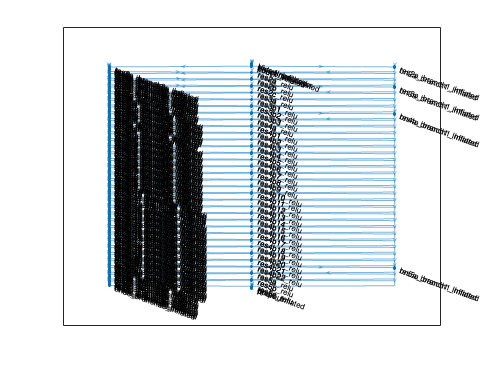

plot(net);
end